# Example use of functions listed in the Standard operating procedure for metabolic reconstruction.

**Author(s): Ines Thiele, LCSB, University of Luxembourg.**

**Reviewer(s): **Catherine Clancy, Stefania Magnusdottir, LCSB, University of Luxembourg.

## **INTRODUCTION**

This tutorial has been adapted and expanded from the protocol for generating metabolic network reconstruction [1].

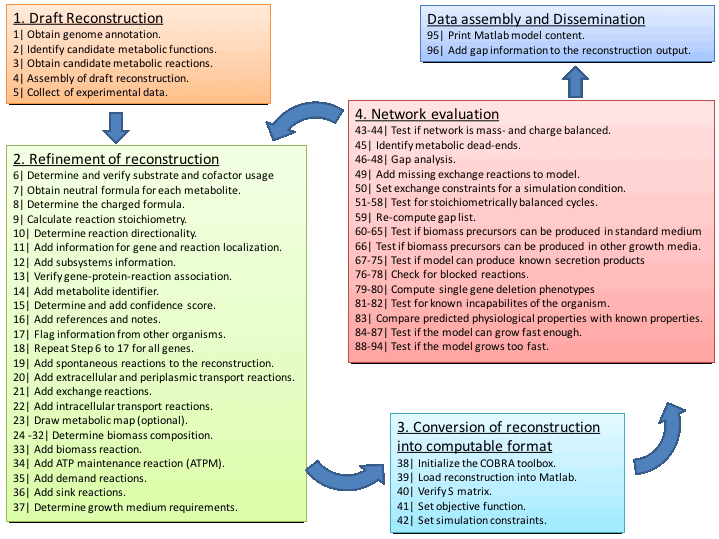

*This tutorial will illustrate the example input for The COBRA Toolbox functions applied in the **steps 38 to 96** of the protocol workflow, using the E. coli core reconstruction [2] as the model of choice. *

*When Matlab/Toolbox commands are following by a ‘;’ the output is not printed. Omitting the ‘;’ invokes printing of the variable content. *

## EQUIPMENT SETUP

## **Step 38.  Initialize The COBRA Toolbox.**

Initialize The COBRA Toolbox using the `initCobraToolbox` function.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

## **Setting the **optimization** solver.**

This tutorial will be run with the `'glpk``'` package, which is a linear programming ('`LP'`) solver. The `'glpk``'` package does not require additional instalation and configuration.

solverName = 'glpk';
solverType = 'LP'; 
changeCobraSolver(solverName, solverType);

However, for the analysis of large models, such as Recon 3, it is not recommended to use the `'glpk``'` package but rather an industrial strength solver, such as the `'gurobi'` package. For detailed information, refer to The COBRA Toolbox [solver instalation guide](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md). 

A solver package may offer different types of optimization programmes to solve a problem. The above example used a LP optimization, other types of optimization programmes include; mixed-integer linear programming ('`MILP`'), quadratic programming ('`QP`'), and mixed-integer quadratic programming ('`MIQP`').

warning off MATLAB:subscripting:noSubscriptsSpecified

## PROCEDURE

## **Step 39.  Load reconstruction into Matlab**. 

The metabolic network reconstruction, containing a reaction and metabolite list, is contained by the file 'Ecoli_core_model.mat'.

modelFileName = 'ecoli_core_model.mat';
modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded
model = readCbModel(modelFileName);
modelEcore = model;

The reconstruction is contained in the resulting model structure.  

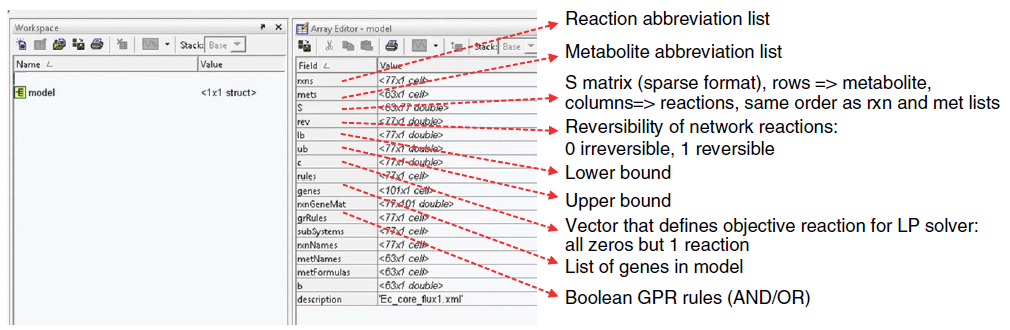

The figure above shows the data contained in the different structure fields. We will use this model structure for all consequent computation if not noted differently.

Use the command `open` to view the model structure in Matlab.

if usejava('desktop') % This line of code is to avoid execution of example in non gui-environments    
    open modelEcore
end

The content of the structure can be assessed as follows:

- You wish to see the abbreviation of the 8th metabolite in the model:

modelEcore.mets{8}

ans = acald[c]

- You wish to see the abbreviation of the 1st reaction in the model:

modelEcore.rxns{1}

ans = ACALD

- You wish to see the entry of the stoichiometric matrix of the 1st reaction (column) and 8th metabolite (row):

modelEcore.S(8,1)

ans =    (1,1)       -1


- Print the reaction formula of the 1st reaction in the model:

printRxnFormula(modelEcore, modelEcore.rxns(1))

ACALD	acald[c] + coa[c] + nad[c] 	<=>	accoa[c] + h[c] + nadh[c] 


ans =     'acald[c] + coa[c] + nad[c]  <=> accoa[c] + h[c] + nadh[c] '


- You want to change the lower bound (lb) of the 5th reaction to 10 mmol/gDW/h (without using any COBRA Toolbox functions):

modelEcore.lb(5) = 10

modelEcore =            rxns: {95×1 cell}
           mets: {72×1 cell}
              S: [72×95 double]
            rev: [95×1 double]
             lb: [95×1 double]
             ub: [95×1 double]
              c: [95×1 double]
          rules: {95×1 cell}
          genes: {137×1 cell}
     rxnGeneMat: [95×137 double]
        grRules: {95×1 cell}
     subSystems: {95×1 cell}
       rxnNames: {95×1 cell}
       metNames: {72×1 cell}
    metFormulas: {72×1 cell}
              b: [72×1 double]
    description: 'Ecoli_core_model'


- You want to add a field to the model structure. 

            A note: 

modelEcore.newField = 'ABC – a note'

modelEcore =            rxns: {95×1 cell}
           mets: {72×1 cell}
              S: [72×95 double]
            rev: [95×1 double]
             lb: [95×1 double]
             ub: [95×1 double]
              c: [95×1 double]
          rules: {95×1 cell}
          genes: {137×1 cell}
     rxnGeneMat: [95×137 double]
        grRules: {95×1 cell}
     subSystems: {95×1 cell}
       rxnNames: {95×1 cell}
       metNames: {72×1 cell}
    metFormulas: {72×1 cell}
              b: [72×1 double]
    description: 'Ecoli_core_model'
       newField: 'ABC – a note'


            An array B = [1 2 3]

B = [1 2 3];
modelEcore.newField = B

modelEcore =            rxns: {95×1 cell}
           mets: {72×1 cell}
              S: [72×95 double]
            rev: [95×1 double]
             lb: [95×1 double]
             ub: [95×1 double]
              c: [95×1 double]
          rules: {95×1 cell}
          genes: {137×1 cell}
     rxnGeneMat: [95×137 double]
        grRules: {95×1 cell}
     subSystems: {95×1 cell}
       rxnNames: {95×1 cell}
       metNames: {72×1 cell}
    metFormulas: {72×1 cell}
              b: [72×1 double]
    description: 'Ecoli_core_model'
       newField: [1 2 3]


- Create a list of strings:

ListStrings = {'A' 'B' 'C'}

ListStrings =     'A'    'B'    'C'


- Create a list of numbers: 

ListNumbers = [1 2 3]

ListNumbers =      1     2     3


- Transpose a list:

ListTranspose = ListNumbers'

ListTranspose =      1
     2
     3


- Find the index of a reaction, e.g., ‘ATPM', in the model 

rxnList = 'ATPM';
rxnID = findRxnIDs(modelEcore, rxnList)

rxnID = 11

## **Step 40.  Verify S matrix.**

Remember that in the S matrix the rows and the columns correspond to the metabolites and the reactions of the model, respectively. The number of non-zero (nz) entries in the S matrix is visualized graphically below using a spy image. 

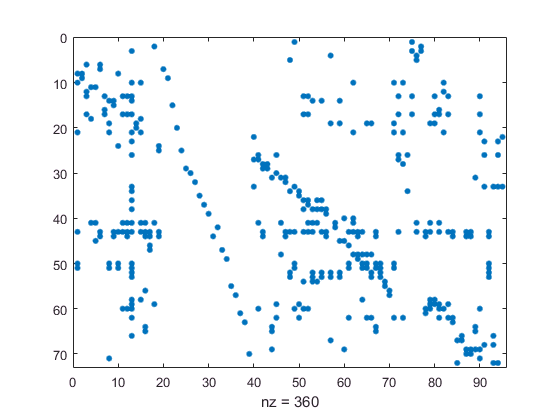

spy(modelEcore.S)

To put this number into perspective, we can calculate the percentage of non-zero entries of S.

[a, b] = size(modelEcore.S);
nz = nnz(modelEcore.S);
Perc_nz = nz*100/(a*b)

Perc_nz = 5.2632

- Many large scale models have less than 1% of non-zero entries in the S matrix.

- Looking at the S matrix is a quick way to see whether there is something obviously wrong with the model and the S matrix.

Here are two further examples of S matrices visualized using a spy image:

E. coli - AF1260 [3]

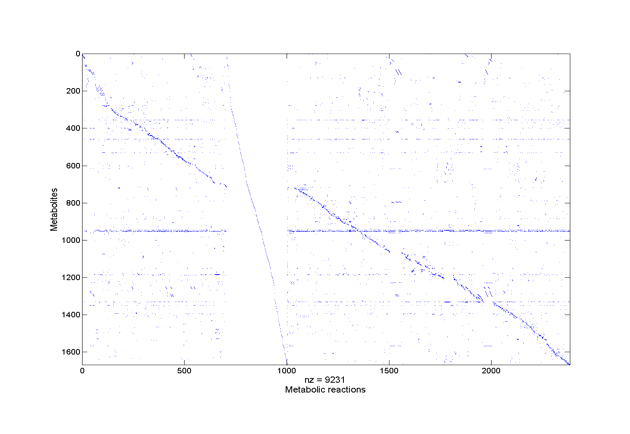

*Geobacter** sulfurreducans [4]*

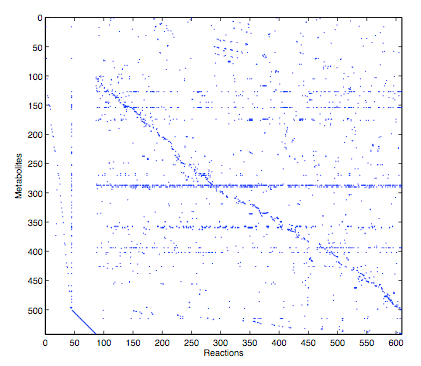

Consider to also use the tutorial on 'Numerical properties of a reconstruction' to investigate the propeties of the S matrix.

## **Step 41.  Set objective function**. 

We will set the biomass reaction (Biomass_Ecoli_core_w_GAM) of the *E. coli *core model as objective function: 

modelEcore = changeObjective(modelEcore, 'Biomass_Ecoli_core_w_GAM');

If you wish to check which reaction(s) make up the objective function and its components, use the following function:

objectiveAbbr = checkObjective(modelEcore)

summaryT =     Coefficient    Metabolite    metID            Reaction            RxnID
    ___________    __________    _____    ________________________    _____

     -1.496        3pg[c]         3       Biomass_Ecoli_core_w_GAM    13   
    -3.7478        accoa[c]      10       Biomass_Ecoli_core_w_GAM    13   
      59.81        adp[c]        13       Biomass_Ecoli_core_w_GAM    13   
     4.1182        akg[c]        14       Biomass_Ecoli_core_w_GAM    13   
     -59.81        atp[c]        17       Biomass_Ecoli_core_w_GAM    13   
     3.7478        coa[c]        21       Biomass_Ecoli_core_w_GAM    13   
     -0.361        e4p[c]        23       Biomass_Ecoli_core_w_GAM    13   
    -0.0709        f6p[c]        26       Biomass_Ecoli_core_w_GAM    13   
     -0.129        g3p[c]        33       Biomass_Ecoli_co

objectiveAbbr =     'Biomass_Ecoli_core_w_GAM'


## **Step 42.  Set simulation constraints**. 

A first step when using and debugging a model should be to identify the constraints that have been applied.

minInf = -1000;
maxInf = 1000;
printConstraints(modelEcore, minInf, maxInf)

MinConstraints:
ACONTb	10
ATPM	8.39
EX_glc(e)	-10
maxConstraints:


- As you can see, only three reactions are constrained in this model. The glucose exchange reaction (EX_glc(e)), the aconitase reaction (ACONTb) and the ATP non-growth associated maintenance reaction (ATPM). Note that in all three cases, a lower bound has been set only but no upper bound.

- The ‘minInf’ and ‘maxInf’ were set to -1000 and 1000, respectively, as these values represent the infinity of the E. coli core model. Other models may have different infinities.

- Note also that the `printConstraints` function returns only those constraints that are greater than -1000 but are smaller than 1000. 

To know which medium constraints are applied to the model, we can use the following function:

printUptakeBound(modelEcore);

EX_co2(e)	-1000	
EX_glc(e)	-10	
EX_h(e)	-1000	
EX_h2o(e)	-1000	
EX_nh4(e)	-1000	
EX_o2(e)	-1000	
EX_pi(e)	-1000	


- As you can see, the model is set to a minimal medium (EX_glc(e) set to -10 mmol/gDW/h) with the presence of oxygen.

Let’s assume that you would like to set the lower bound of the ATP maintenance reaction (‘ATPM’) to 8.39 mmol/gDW/h:

modelEcore = changeRxnBounds(modelEcore, 'ATPM', 8.39, 'l');

            and the upper bound of the ‘ATPM’ reaction to 8.39 mmol/gDW/h: 

modelEcore = changeRxnBounds(modelEcore, 'ATPM', 8.39, 'u');

To change both the lower and upper bound in the same command use: 

modelEcore = changeRxnBounds(modelEcore, 'ATPM', 8.39, 'b');

Let’s assume that you would like to set the lower bound of the ‘ATPM’ reaction to 8.39 mmol/gDW/h and the ATP synthetase (‘ATPS4r’) to an upper bound of 100 mmol/gDW/h:

modelEcore = changeRxnBounds(modelEcore, 'ATPM', 8.39, 'l' );
modelEcore = changeRxnBounds(modelEcore, 'ATPS4r', 100, 'u');

The set constraints can be checked using the following function:

printConstraints(modelEcore, -1000,1000)

MinConstraints:
ACONTb	10
ATPM	8.39
EX_glc(e)	-10
maxConstraints:
ATPM	8.39
ATPS4r	100


## **Steps 43 - 44.  Test if network is mass- and charge balanced.**

Check mass- and charge balance for the entire network of the model:

[massImbalance, imBalancedMass, imBalancedCharge, imBalancedRxnBool, Elements, missingFormulaeBool, balancedMetBool] = checkMassChargeBalance(modelEcore);

## **Step 45.  Identify metabolic dead-ends**

Detect deadend metabolites:

outputMets = detectDeadEnds(modelEcore)

outputMets =     30
    32
    37
    49


Print the corresponding metabolite names:

DeadEnds = modelEcore.mets(outputMets)

DeadEnds =     'fru[e]'
    'fum[e]'
    'gln-L[e]'
    'mal-L[e]'


- These metabolites are only produced or consumed in the network and the associated reactions are blocked reactions.

Identify associated reactions:

[rxnList, rxnFormulaList] = findRxnsFromMets(modelEcore, DeadEnds)

rxnList =     'EX_fru(e)'
    'EX_fum(e)'
    'EX_gln_L(e)'
    'EX_mal_L(e)'
    'FRUpts2'
    'FUMt2_2'
    'GLNabc'
    'MALt2_2'


rxnFormulaList =     'fru[e]  -> '
    'fum[e]  -> '
    'gln-L[e]  -> '
    'mal-L[e]  -> '
    'fru[e] + pep[c]  -> f6p[c] + pyr[c] '
    'fum[e] + 2 h[e]  -> fum[c] + 2 h[c] '
    'atp[c] + gln-L[e] + h2o[c]  -> adp[c] + gln-L[c] + h[c] + pi[c] '
    '2 h[e] + mal-L[e]  -> 2 h[c] + mal-L[c] '


- As you can see, these metabolites have each two reactions associated. Why are they then detected as deadend metabolites?

Let's have a look at the lower and upper bounds of these reactions:

modelEcore.lb(find(ismember(modelEcore.rxns, rxnList)))

ans =      0
     0
     0
     0
     0
     0
     0
     0


modelEcore.ub(find(ismember(modelEcore.rxns, rxnList)))

ans =         1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000


- In this particular case, these four metabolites are deadend metabolites as the associated exchange reactions are set to lb=0 (i.e., no uptake is permitted). As we are interested in dead-end metabolites that are generally only consumed or produced by the network, irrespective of the applied constraints, we will set the lower bound of all exchange reaction to -1000 and the upper bound to 1000.

modelEcore_New = modelEcore;
modelEcore_New.lb(strmatch('EX_', modelEcore_New.rxns)) = -1000;
modelEcore_New.ub(strmatch('EX_', modelEcore_New.rxns)) = 1000;

Now we repeat the identification of deadend metabolites:

outputMets = detectDeadEnds(modelEcore_New)


outputMets =

  0×1 empty double column vector



DeadEnds = modelEcore_New.mets(outputMets)


DeadEnds =

  0×1 empty cell array



[rxnList, rxnFormulaList] = findRxnsFromMets(modelEcore_New, DeadEnds)


rxnList =

  0×1 empty cell array




rxnFormulaList =

  0×0 empty cell array



- And indeed no deadend metabolites remain. This example also illustrates how such issues can be fixed - one option is to revert the directionality of the associated reactions. 

- Note that changing the directionality must be carefully evaluated in each case, to ensure that the resulting model is biologically accurate. For instance, changing the directionality of the 'FRUpts_2' reaction would have not been biologically meaningful, as the Phosphotransferase system is known to be unidirectional under physiologically relevant conditions.

## Steps 46 - 49. Refer to 'gap analysis' tutorial.

## Step 50. Set exchange constraints for a simulation condition.

The COBRA Toolbox function, `changeRxnBounds,`is used to set constraints on a reaction which is demonstrated in step 67 of this tutorial.  

## **Steps 51 - 59. Test for stoichiometrically balanced cycles (SBCs).**

SBCs or Type III pathways, are formed by internal network reactions and can carry fluxes despite closed exchange reactions (closed system). Therefore, use the following `testForTypeIIIPathways` function: 

- The indices of the exchange reactions ('EX_') are input as a list. 

- The output filename can be specified with ‘test’, it receives automatically the extension ‘.expa’. The filename is optional, the default name is: 'ModelTestTypeIII'

selExc = findExcRxns(modelEcore);
listExch = find(selExc);
try
    testForTypeIIIPathways(modelEcore, listExch, 'test');
catch ME
    getReport(ME)
end

ans = Error using fprintf
Function is not defined for sparse inputs.

Error in convertModelToEX (line 54)
                fprintf(fid, '%i\t%s\t', model.S(reactionPlace(j), i), model.mets{reactionPlace(j)});

Error in testForTypeIIIPathways (line 48)
convertModelToEX(model

- *This error message is returned from X3.exe since there are no SBCs in the E. coli core network.*

## ***Steps 60 - 66. Test if biomass precursors can be produced in standard medium***

***%TODO steps 64 to 66 are not referenced in this section. ***

**60.**  Obtain a list of biomass components:

BiomassComponents = modelEcore.mets(find(modelEcore.S(:, strmatch('Biomass', modelEcore.rxns))))

BiomassComponents =     '3pg[c]'
    'accoa[c]'
    'adp[c]'
    'akg[c]'
    'atp[c]'
    'coa[c]'
    'e4p[c]'
    'f6p[c]'
    'g3p[c]'
    'g6p[c]'
    'gln-L[c]'
    'glu-L[c]'
    'h2o[c]'
    'h[c]'
    'nad[c]'
    'nadh[c]'
    'nadp[c]'
    'nadph[c]'
    'oaa[c]'
    'pep[c]'
    'pi[c]'
    'pyr[c]'
    'r5p[c]'


**61.**  Add a demand function for each biomass precursor:

[modelEcore_NEW, rxnNames] = addDemandReaction(modelEcore, BiomassComponents);

DM_3pg[c]	3pg[c] 	->	
DM_accoa[c]	accoa[c] 	->	
DM_adp[c]	adp[c] 	->	
DM_akg[c]	akg[c] 	->	
DM_atp[c]	atp[c] 	->	
DM_coa[c]	coa[c] 	->	
DM_e4p[c]	e4p[c] 	->	
DM_f6p[c]	f6p[c] 	->	
DM_g3p[c]	g3p[c] 	->	
DM_g6p[c]	g6p[c] 	->	
DM_gln-L[c]	gln-L[c] 	->	
DM_glu-L[c]	glu-L[c] 	->	
DM_h2o[c]	h2o[c] 	->	
DM_h[c]	h[c] 	->	
DM_nad[c]	nad[c] 	->	
DM_nadh[c]	nadh[c] 	->	
DM_nadp[c]	nadp[c] 	->	
DM_nadph[c]	nadph[c] 	->	
DM_oaa[c]	oaa[c] 	->	
DM_pep[c]	pep[c] 	->	
DM_pi[c]	pi[c] 	->	
DM_pyr[c]	pyr[c] 	->	
DM_r5p[c]	r5p[c] 	->	


*For each biomass component i, perform the following test:*

for i = 1 : length(BiomassComponents)

**62.**  Change objective function to the demand function:

    modelEcore_NEW = changeObjective(modelEcore_NEW, rxnNames(i));

ans =     '3pg[c]'      [    10.0000]
    'accoa[c]'    [-1.1313e-16]
    'adp[c]'      [-1.7764e-15]
    'akg[c]'      [    10.0000]
    'atp[c]'      [          0]
    'coa[c]'      [ 3.4642e-15]
    'e4p[c]'      [     7.5000]
    'f6p[c]'      [     5.0000]
    'g3p[c]'      [         10]
    'g6p[c]'      [     5.0000]
    'gln-L[c]'    [         10]
    'glu-L[c]'    [    10.0000]
    'h2o[c]'      [       1000]
    'h[c]'        [       1000]
    'nad[c]'      [ 8.3105e-16]
    'nadh[c]'     [ 2.9009e-27]
    'nadp[c]'     [ 9.1312e-29]
    'nadph[c]'    [-1.1583e-16]
    'oaa[c]'      [    10.0000]
    'pep[c]'      [    10.0000]
    'pi[c]'       [ 1.0000e+03]
    'pyr[c]'      [    10.0000]
    'r5p[c]'      [     6.0000]


**63.**  Maximize (‘max’) for new objective function (Demand function)

    FBAsolution = optimizeCbModel(modelEcore_NEW, 'max');

MinConstraints:
ACONTb	10
ATPM	8.39
EX_glc(e)	-10
maxConstraints:
ATPM	8.39
ATPS4r	100


- FBAsolution is a structure containing the result of the optimization. FBAsolution.f gives the maximal value of the objective reaction (i.e., 'DM_pep[c]'), which is greater than 0 mmol/gDW/h. This means that our *E. coli *core model can produce pep[c]. 

- Store each solution in a vector:

    BiomassComponentsValue(i,1) = FBAsolution.f;
end

summaryT =     Coefficient    Metabolite    metID            Reaction            RxnID
    ___________    __________    _____    ________________________    _____

     -1.496        3pg[c]         3       Biomass_Ecoli_core_w_GAM    13   
    -3.7478        accoa[c]      10       Biomass_Ecoli_core_w_GAM    13   
      59.81        adp[c]        13       Biomass_Ecoli_core_w_GAM    13   
     4.1182        akg[c]        14       Biomass_Ecoli_core_w_GAM    13   
     -59.81        atp[c]        17       Biomass_Ecoli_core_w_GAM    13   
     3.7478        coa[c]        21       Biomass_Ecoli_core_w_GAM    13   
     -0.361        e4p[c]        23       Biomass_Ecoli_core_w_GAM    13   
    -0.0709        f6p[c]        26       Biomass_Ecoli_core_w_GAM    13   
     -0.129        g3p[c]        33       Biomass_Ecoli_co

objectiveAbbr =     'Biomass_Ecoli_core_w_GAM'


- Print each BiomassComponent and the corresponding value:

[BiomassComponents  num2cell(BiomassComponentsValue)]

BiomassComponentsPos =     'adp[c]'
    'akg[c]'
    'coa[c]'
    'h[c]'
    'nadh[c]'
    'nadp[c]'
    'pi[c]'


- As we can see, not all biomass components (or rather their corresponding demand reaction) can have a non-zero flux. Why is that?

- Just to remember us, the model constraints are:

printConstraints(modelEcore_NEW, -1000,1000)

BiomassComponentsNeg =     '3pg[c]'
    'accoa[c]'
    'atp[c]'
    'e4p[c]'
    'f6p[c]'
    'g3p[c]'
    'g6p[c]'
    'gln-L[c]'
    'glu-L[c]'
    'h2o[c]'
    'nad[c]'
    'nadph[c]'
    'oaa[c]'
    'pep[c]'
    'pyr[c]'
    'r5p[c]'


- Note that only those constraints will be printed that are smaller greater than -1000 and smaller than 1000.

- Let's revisit how the biomass reaction is formulated in this model:

modelEcore = changeObjective(modelEcore, modelEcore.rxns(strmatch('Biomass', modelEcore.rxns)));

sink_adp[c]	adp[c] 	<=>	
sink_akg[c]	akg[c] 	<=>	
sink_coa[c]	coa[c] 	<=>	
sink_h[c]	h[c] 	<=>	
sink_nadh[c]	nadh[c] 	<=>	
sink_nadp[c]	nadp[c] 	<=>	
sink_pi[c]	pi[c] 	<=>	


[objectiveAbbr] = checkObjective(modelEcore)

DM_3pg[c]	3pg[c] 	->	
DM_accoa[c]	accoa[c] 	->	
DM_atp[c]	atp[c] 	->	
DM_e4p[c]	e4p[c] 	->	
DM_f6p[c]	f6p[c] 	->	
DM_g3p[c]	g3p[c] 	->	
DM_g6p[c]	g6p[c] 	->	
DM_gln-L[c]	gln-L[c] 	->	
DM_glu-L[c]	glu-L[c] 	->	
DM_h2o[c]	h2o[c] 	->	
DM_nad[c]	nad[c] 	->	
DM_nadph[c]	nadph[c] 	->	
DM_oaa[c]	oaa[c] 	->	
DM_pep[c]	pep[c] 	->	
DM_pyr[c]	pyr[c] 	->	
DM_r5p[c]	r5p[c] 	->	


- As you can see, there are numerous metabolites that have a positive coefficient in the biomass equation, meaning that they are produced by the biomass reaction and thus we need to test whether these metabolites can be removed, rather than produced by the model. Hence, we need to add sink reactions (rather than demand reactions) and minimize them:

**64.**  Identify reactions that are mainly responsible for synthesizing the biomass component.

- Let's get all biomass components with a positive coefficient in the biomass reaction:

BiomassComponentsPos = modelEcore.mets(find(modelEcore.S(:, strmatch('Biomass', modelEcore.rxns)) > 0))
BiomassComponentsNeg = modelEcore.mets(find(modelEcore.S(:, strmatch('Biomass', modelEcore.rxns)) < 0))

**65.**  For each of these metabolites, we add sink reactions for components with a positive coefficient and demand reactions for components with a negative coefficient.

[modelEcore_NEW] = addSinkReactions(modelEcore, BiomassComponentsPos);

ans =     'adp[c]'     [    -1000]
    'akg[c]'     [    -1000]
    'coa[c]'     [-663.3333]
    'h[c]'       [    -1000]
    'nadh[c]'    [    -1000]
    'nadp[c]'    [    -1000]
    'pi[c]'      [    -1000]


[modelEcore_NEW, rxnNames] = addDemandReaction(modelEcore_NEW, BiomassComponentsNeg);

- Note that we added both the sink and the demand reactions to the model simultanously. The reason for this is that metabolites such as coa and accoa, or nadh and nad, are not produced or consumed in this model but only recycled. Hence, for obtaining a non-zero flux for any of the associated sink or demand reactions one needs to add the reaction pair. In larger networks (than the *E. coli* core model) this will be less of a problem as they capture the biosynthetic pathways for these metabolites.

Now lets repeat the analysis (note that we minimize the objective):

for i = 1 : length(BiomassComponentsPos)
    modelEcore_NEW = changeObjective(modelEcore_NEW, strcat('sink_', BiomassComponentsPos(i)));
    FBAsolution = optimizeCbModel(modelEcore_NEW, 'min');
    BiomassComponentsValuePos(i, 1) = FBAsolution.f;
end
[BiomassComponentsPos  num2cell(BiomassComponentsValuePos)]

ans =     '3pg[c]'      [  555.8050]
    'accoa[c]'    [  663.3333]
    'atp[c]'      [      1000]
    'e4p[c]'      [  280.4025]
    'f6p[c]'      [  186.9350]
    'g3p[c]'      [  370.5367]
    'g6p[c]'      [  186.9350]
    'gln-L[c]'    [       500]
    'glu-L[c]'    [1.0000e+03]
    'h2o[c]'      [      1000]
    'nad[c]'      [1.0000e+03]
    'nadph[c]'    [      1000]
    'oaa[c]'      [  990.1464]
    'pep[c]'      [  555.8050]
    'pyr[c]'      [  992.5000]
    'r5p[c]'      [  224.3220]


- All these metabolites can be removed by the model.

- We repeat the same analysis for all negative biomass components.

Now lets repeat the analysis (note that we maximize the objective):

for i = 1 : length(BiomassComponentsNeg)
    modelEcore_NEW = changeObjective(modelEcore_NEW, strcat('DM_', BiomassComponentsNeg(i)));

ans = 0.7082

    FBAsolution = optimizeCbModel(modelEcore_NEW, 'max');
    BiomassComponentsValueNeg(i, 1) = FBAsolution.f;

ACONTa	10	
ACONTb	10	
ADK1	9.68291	
ATPM	8.39	
ATPS4r	61.4747	
Biomass_Ecoli_core_w_GAM	0.708235	
CO2t	-29.8607	
CS	10	
CYTBD	58.0838	
ENO	17.0578	
EX_co2(e)	29.8607	
EX_glc(e)	-10	
EX_h(e)	14.2072	
EX_h2o(e)	35.0198	
EX_nh4(e)	-3.86187	
EX_o2(e)	-29.0419	
EX_pi(e)	-2.60539	
FBA	9.29552	
FUM	9.23588	
GAPD	18.1173	
GLCpts	10	
GLNS	0.181096	
GLUDy	-3.68077	
H2Ot	-35.0198	
ICDHyr	0.764115	
ICL	9.23588	
MALS	9.23588	
MDH	-5.10764	
ME2	23.5794	
NADH16	48.8479	
NADTRHD	11.4359	
NH4t	3.86187	
O2t	29.0419	
PDH	21.8902	
PFK	9.29552	
PGI	9.85481	
PGK	-18.1173	
PGM	-17.0578	
PIt2r	2.60539	
PPC	16.373	
PPS	9.68291	
RPE	-0.50908	
RPI	-0.50908	
SUCDi	9.23588	
TALA	-0.126703	
TKT1	-0.126703	
TKT2	-0.382376	
TPI	9.29552	


end
[BiomassComponentsNeg  num2cell(BiomassComponentsValueNeg)]

- All these biomass precursors can be produced by the model. Hence a non-zero, positive flux through the biomass reaction should be possible:

FBAsolution = optimizeCbModel(modelEcore, 'max');

ans = 0.7082

FBAsolution.f

ACONTa	10	
ACONTb	10	
AKGDH	3.69917	
ATPM	8.39	
ATPS4r	31.7196	
Biomass_Ecoli_core_w_GAM	0.708235	
CO2t	-11.6696	
CS	10	
CYTBD	39.8928	
ENO	17.0578	
EX_co2(e)	11.6696	
EX_for(e)	18.191	
EX_glc(e)	-10	
EX_h(e)	32.3982	
EX_h2o(e)	16.8287	
EX_nh4(e)	-3.86187	
EX_o2(e)	-19.9464	
EX_pi(e)	-2.60539	
FBA	9.29552	
FORti	18.191	
FUM	9.23588	
GAPD	18.1173	
GLCpts	10	
GLNS	0.181096	
GLUDy	-3.68077	
H2Ot	-16.8287	
ICDHyr	4.46328	
ICL	5.53672	
MALS	5.53672	
MDH	11.2654	
ME2	3.5072	
NADH16	30.6569	
NH4t	3.86187	
O2t	19.9464	
PFK	9.29552	
PFL	18.191	
PGI	9.85481	
PGK	-18.1173	
PGM	-17.0578	
PIt2r	2.60539	
PYK	6.69013	
RPE	-0.50908	
RPI	-0.50908	
SUCDi	9.23588	
SUCOAS	-3.69917	
TALA	-0.126703	
THD2	4.93711	
TKT1	-0.126703	
TKT2	-0.382376	
TPI	9.29552	


FBAsolution.x contains the flux value for each reaction in the network. To view the flux values use:

printFluxVector(modelEcore, FBAsolution.x, 'true')

- To see which network reactions participate in the optimal solution. Keep in mind that there may be more than one optimal solution (so-called alternate optimal solutions, which have the same optimal value for the objective function but the internal flux distribution may be different) .

- Compare this solution with a sparse FBA solution, which returns an optimal flux distribution with the least number of active model reactions. Note that the underlying algorithm is an approximation to the exact sparsest solution and also that there may be alternative optimal solutions with equal numbers of active reactions.

FBAsolution = optimizeCbModel(modelEcore, 'max', 'zero');
FBAsolution.f
printFluxVector(modelEcore, FBAsolution.x, 'true')

**66.**  To test whether the biomass precursors can be produced in other growth media, repeat steps 60-65.

## **Steps 67 - 70. Test if model can produce known secretion products.**

**67. **Collect a list of known secretion products and medium conditions.

For this example, acetate secretion ('EX_ac(e)') was chosen and let's require that secretion flux is at least 2 mmol/gDW/h (i.e. the lower bound is constrained to 2).

modelEcore_New = changeRxnBounds(modelEcore, 'EX_ac(e)', 2, 'l'); 

**68. ** Set the constraints to the desired medium condition (e.g., minimal medium + carbon source). For changing the constraints use the following function:

modelEcore_New = changeRxnBounds(modelEcore, {'EX_glc(e)' 'EX_o2(e)'}, [-10 -18.5], 'l');

FBAsolution =          full: [95×1 double]
          obj: 0.6411
        rcost: [95×1 double]
         dual: [72×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.0260
        basis: []
            x: [95×1 double]
            f: 0.6411
            y: [72×1 double]
            w: [95×1 double]
            v: [95×1 double]


- If the model is required to grow in addition to producing the by-product, set the lower bound of the biomass reaction to the corresponding value required for growth.   

**Note: **If the model is required to grow in addition to producing the by-product, set the lower bound of the biomass reaction to the corresponding value required for growth. We determine the value based on the following FBA solution.

- Optimize for growth:

modelEcore_New = changeObjective(modelEcore_New, 'Biomass_Ecoli_core_w_GAM');
FBAsolution = optimizeCbModel(modelEcore_New, 'max')

- Set the lower bound of the biomass reaction to the value of the FBA solution:

modelEcore_New = changeRxnBounds(modelEcore_New, 'Biomass_Ecoli_core_w_GAM', 0.64, 'l');

- Note that the maximally possible biomass reaction flux decreased substantially, with these additional constraints.

**69.  **Change the objective function to the exchange reaction of your secretion product (i.e., acetate):  

modelEcore_New = changeObjective(modelEcore_New, 'EX_ac(e)');

FBAsolution =          full: [95×1 double]
          obj: 0.0448
        rcost: [95×1 double]
         dual: [72×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.0260
        basis: []
            x: [95×1 double]
            f: 0.0448
            y: [72×1 double]
            w: [95×1 double]
            v: [95×1 double]


**70.  **Maximize (‘max’) for the new objective function (as a secretion is expected to have a positive flux value, see Figure ):

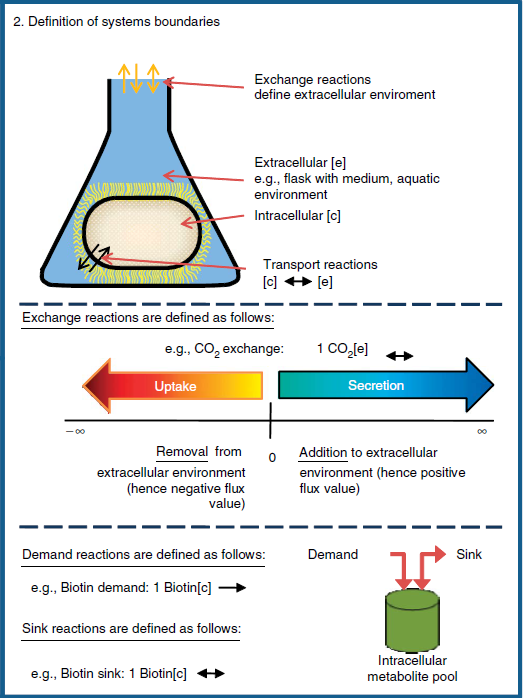

FBAsolution = optimizeCbModel (modelEcore_New, 'max')

MinConstraints:
ACONTb	10
ATPM	8.39
Biomass_Ecoli_core_w_GAM	0.64
EX_glc(e)	-10
EX_o2(e)	-18.5
maxConstraints:
ATPM	8.39
ATPS4r	100


- It seems that the model can produce 3.5x mmol/gDW/h of acetate with the following constraints:

printConstraints(modelEcore_New, -1000,1000)

## ***Steps 71 - 75. Test if model can produce a certain ratio of two secretion products.*** 

Acetate and Formate secretion are the two secretion products used in this example. 

**71. ** Set the constraints to the desired medium condition (e.g., minimal medium + carbon source). As shown above in step 68.  

**72. ** Let's verify that both metabolites can be secreted independently. Repeat steps 69 and 70.

modelEcoreAc = changeObjective(modelEcore, 'EX_ac(e)');

FBAsolution =          full: [95×1 double]
          obj: 10.0000
        rcost: [95×1 double]
         dual: [72×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.0270
        basis: []
            x: [95×1 double]
            f: 10.0000
            y: [72×1 double]
            w: [95×1 double]
            v: [95×1 double]


FBAsolution = optimizeCbModel(modelEcoreAc, 'max')
modelEcoreFor = changeObjective(modelEcore, 'EX_for(e)');

FBAsolution =          full: [95×1 double]
          obj: 40.0000
        rcost: [95×1 double]
         dual: [72×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.0260
        basis: []
            x: [95×1 double]
            f: 40.0000
            y: [72×1 double]
            w: [95×1 double]
            v: [95×1 double]


FBAsolution = optimizeCbModel(modelEcoreFor, 'max')

**73.**  Add a row to the S matrix to couple the by-product secretion reactions:

modelEcore_NEW = addRatioReaction(modelEcore, {'EX_ac(e)' 'EX_for(e)'}, [1 1]);

- Acetate and Formate secretion are coupled to a ratio of 1:1.

Also, let's require that the acetate secretion flux is at least 1 mmol/gDW/h (i.e. the lower bound is constrained to 1).

modelEcore_NEW = changeRxnBounds(modelEcore_NEW, 'EX_ac(e)', 1, 'l');

**Note: **If the model is required to grow in addition to producing the by-product, set the lower bound of the biomass reaction to the corresponding value required for growth. We determine the value based on the following FBA solution.

- Optimize for growth:

modelEcore_NEW = changeObjective(modelEcore_NEW, 'Biomass_Ecoli_core_w_GAM');
FBAsolution = optimizeCbModel(modelEcore_NEW, 'max')

FBAsolution =          full: [95×1 double]
          obj: 0.6374
        rcost: [95×1 double]
         dual: [73×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.0260
        basis: []
            x: [95×1 double]
            f: 0.6374
            y: [73×1 double]
            w: [95×1 double]
            v: [95×1 double]


- Note that the maximally possible biomass reaction flux decreased due to the additional constraints.

- Set the lower bound of the biomass reaction to the value of the FBA solution:

modelEcore_NEW = changeRxnBounds(modelEcore_NEW, 'Biomass_Ecoli_core_w_GAM', 0.63, 'l');

What is the flux through the two secretion reactions:

FBAsolution.x(find(ismember(modelEcore_NEW.rxns, 'EX_for(e)')))

ans = 1

FBAsolution.x(find(ismember(modelEcore_NEW.rxns, 'EX_ac(e)')))

ans = 1

- Keep in mind that the `optimizeCbModel` only returns one of the possible flux distributions with maximal biomass yield.

**74.**  Change the objective function to the exchange reaction of one of your secretion products: 

modelEcore_NEW = changeObjective(modelEcore_NEW, 'EX_ac(e)');

**75.**  Maximize for the new objective function (as a secretion is expected to have a positive flux value):

FBAsolution = optimizeCbModel (modelEcore_NEW, 'max')

FBAsolution =          full: [95×1 double]
          obj: 1.1047
        rcost: [95×1 double]
         dual: [73×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.0260
        basis: []
            x: [95×1 double]
            f: 1.1047
            y: [73×1 double]
            w: [95×1 double]
            v: [95×1 double]


- Check that the second secretion product can be produced in the defined ratio:

FBAsolution.x(find(ismember(modelEcore_NEW.rxns, 'EX_for(e)')))

ans = 1.1047

## Steps 76 - 77. Check for blocked reactions.

**76. ** Change simulation conditions to rich medium or open all exchange reactions.

- Identify the exchange reactions and set the reaction values to − infinity (e.g., − 1,000) and + infinity (e.g., + 1,000):

selExc = findExcRxns(modelEcore);
ExR = modelEcore.rxns(selExc);
modelEcore_Open =  changeRxnBounds(modelEcore, ExR, -1000, 'l');
modelEcore_Open =  changeRxnBounds(modelEcore_Open, ExR, 1000, 'u');

- Verify the constraints on the model:

printConstraints(modelEcore_Open, -1000, 1000)

MinConstraints:
ACONTb	10
ATPM	8.39
maxConstraints:
ATPM	8.39
ATPS4r	100


printUptakeBound(modelEcore_Open);

EX_ac(e)	-1000	
EX_acald(e)	-1000	
EX_akg(e)	-1000	
EX_co2(e)	-1000	
EX_etoh(e)	-1000	
EX_for(e)	-1000	
EX_fru(e)	-1000	
EX_fum(e)	-1000	
EX_glc(e)	-1000	
EX_gln_L(e)	-1000	
EX_glu_L(e)	-1000	
EX_h(e)	-1000	
EX_h2o(e)	-1000	
EX_lac_D(e)	-1000	
EX_mal_L(e)	-1000	
EX_nh4(e)	-1000	
EX_o2(e)	-1000	
EX_pi(e)	-1000	
EX_pyr(e)	-1000	
EX_succ(e)	-1000	


**77.**  Run analysis for blocked reactions. The `findBlockedReaction` function returns a list of blocked reactions (‘BlockedReactions’).

BlockedReactions = findBlockedReaction(modelEcore_Open)

Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers.


BlockedReactions =     {''}


- The answer is an empty array since the* E. coli *core network has no blocked reactions. 

- If the model contains blocked reactions, please refer to the tutorial for 'gap filling' on how to proceed.

## Steps 79 - 80. Compute single gene deletion phenotypes

**7****9.**  Use The Cobra Toolbox function, `singleGeneDeletion, `to simulate gene deletion:

[grRatio, grRateKO, grRateWT, hasEffect] = singleGeneDeletion(modelEcore);

Single gene deletion analysis in progress ...

- The variable 'hasEffect' is returned, and an entry of 1 in the vector indicate that a gene deletion had an affect on the objective function (here, growth rate). 

Let's visualize hasEffect: 

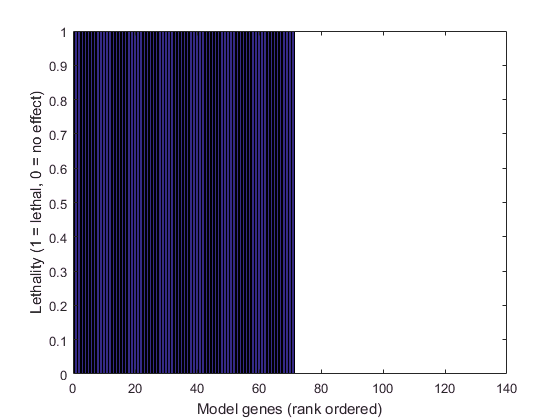

bar(sort(hasEffect,'descend'))
xlabel('Model genes (rank ordered)');
ylabel('Lethality (1 = lethal, 0 = no effect)')

How many genes are in my model?

length(modelEcore.genes)

ans = 137

How many genes have an effect and which ones?

length(find(hasEffect))

ans = 71

Which gene deletions had an affect?

modelEcore.genes(find(hasEffect))

ans =     'b0114'
    'b0115'
    'b0116'
    'b0474'
    'b0720'
    'b0721'
    'b0722'
    'b0723'
    'b0724'
    'b0726'
    'b0727'
    'b0728'
    'b0729'
    'b0767'
    'b0809'
    'b0810'
    'b0811'
    'b1136'
    'b1479'
    'b1602'
    'b1603'
    'b1702'
    'b1761'
    'b1779'
    'b1817'
    'b1818'
    'b1819'
    'b1852'
    'b2029'
    'b2276'
    'b2277'
    'b2278'
    'b2279'
    'b2280'
    'b2281'
    'b2282'
    'b2283'
    'b2284'
    'b2285'
    'b2286'
    'b2287'
    'b2288'
    'b2415'
    'b2416'
    'b2463'
    'b2587'
    'b2779'
    'b2926'
    'b3212'
    'b3213'
    'b3236'
    'b3403'
    'b3528'
    'b3731'
    'b3732'
    'b3733'
    'b3734'
    'b3735'
    'b3736'
    'b3737'
    'b3738'
    'b3919'
    'b3956'
    'b4015'
    'b4025'
    'b4077'
    'b4151'
    'b4152'
    'b4153'
    'b4154'
    's0001'


Which gene deletions are lethal?

- We define all growth rates lower than 0.001 1/hr as no growth. 

tol = 1e-3;
LethalGenes = modelEcore.genes(find(grRateKO < tol))

LethalGenes =     'b0721'
    'b0722'
    'b0723'
    'b0724'
    'b1136'
    'b3919'


length(LethalGenes)

ans = 6

- Plot the effect of gene deletions on growth rate:

Some entries in 'grRateKO' maybe NaN. This is because the model is infeasible for those knockouts due to the lower bound on the 'ATPM'. We will replace those instances by zero.

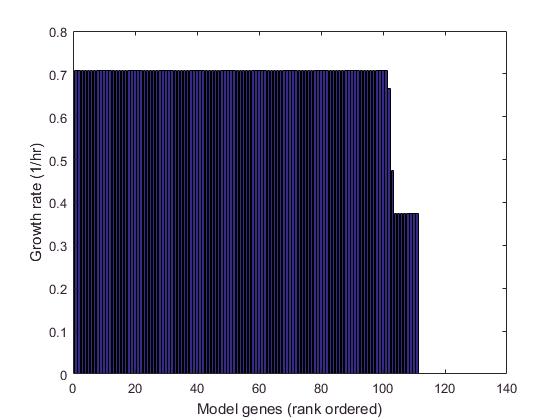

grRateKO(isnan(grRateKO)) = 0;

bar(sort(grRateKO, 'descend'));
xlabel('Model genes (rank ordered)');
ylabel('Growth rate (1/hr)')

**80. **Compare with experimental data.

- Are those genes known to be lethal in the organism (in vivo)?

## Steps 81-82. Test for known incapabilities of the organism.

**81.** Set simulation condition for comparisons with known incapabilities.

- Change the objective function. Test for incapability by maximizing for the objective function.

- If incapable, no solution or zero flux should be returned.

modelIncapable = changeRxnBounds(modelEcore, 'EX_glc(e)', 0, 'l');
modelIncapable = changeRxnBounds(modelIncapable, 'EX_ac(e)', -10, 'l');
FBAsolution = optimizeCbModel(modelIncapable, 'max', false)

FBAsolution =          full: [95×1 double]
          obj: 5.2916e-16
        rcost: [95×1 double]
         dual: [72×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.0380
        basis: []
            x: [95×1 double]
            f: 5.2916e-16
            y: [72×1 double]
            w: [95×1 double]
            v: [95×1 double]


- *E. coli* cannot grow *in vitro* on acetate as a sole carbon source, and the *in silco* model is also incapable of that

**82.** If the *in silico* model is capable of a function that the organism is incapable of *in vitro*, use single-reaction deletion to identify candidate reactions that enable the model’s capability despite known incapability (see step 79). 

- Such reactions need to be manually evaluated.

## Step 83. Compare predicted physiological properties with known properties.

Use previous steps of the tutorial and compare known physiological, phenotypic, or genetic properties with the model capabilities.

## Steps 84-87. Test if the model can grow fast enough.

**84.** Optimize for biomass reaction in different medium conditions and compare with experimental data.

- If the model does not grow, check boundary constraints, simulation conditions, and network completeness.

- If the model grows too slowly, there are multiple possible issues. Start by checking boundary constraints and reaction directionality.

**85.** Test if any of the medium components are growth limiting.

- If yes, increase uptake rate of one substrate at a time and maximize biomass (step 86).

**86.** Maximize for biomass.

- If the biomass flux is higher, the substrate is growth limiting. Such substrates can give information about possible gaps in the network.

**87.** Determine reduced costs when maximizing biomass (see steps 88-89).

- Find reactions with low reduced cost values.

- Increasing flux through identified reactions will lead to higher biomass flux.

## ***Steps 88 - 89. Test if the model grows too fast. ***

When optimization results for a biomass reaction in different medium conditions are compared with experimental data, one can evaluate if the model grows too fast. Analysis of modeling constraints, reduced cost and single gene deletion, are helpful in the evaluation of growth conditions.  

**88.  **Determine the reduced cost associated with network reactions when optimizing for an objective function: 

FBAsolution = optimizeCbModel(modelEcore, 'max', false)

FBAsolution =          full: [95×1 double]
          obj: 0.7082
        rcost: [95×1 double]
         dual: [72×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.0310
        basis: []
            x: [95×1 double]
            f: 0.7082
            y: [72×1 double]
            w: [95×1 double]
            v: [95×1 double]


- FBAsolution.y contains the shadow price for each metabolite and FBAsolution.w contains the reduced cost for each network reaction. 

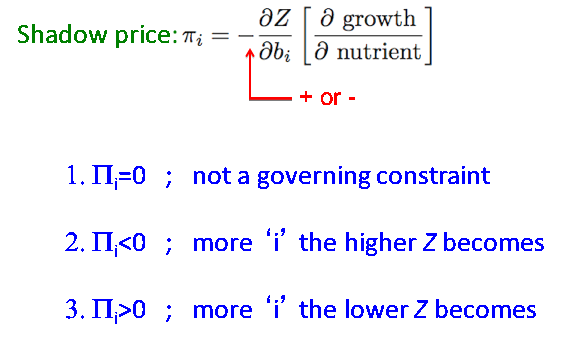

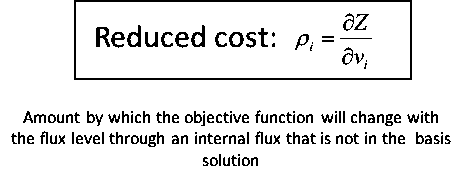

- We find the reduced cost particularly informative to identify constraints that limit the maximal value of the objective function. 

- Note that by definition the reduced cost has a negative sign. Meaning that a reaction A with a reduced cost of 35 would lead to an increase in the objective value by 35 if the flux through this reaction would be increased by 1 flux unit.

Print those reactions that have the smallest reduced cost associated:

[a,b] = sort(FBAsolution.w, 'descend');
modelEcore.rxns(b(1:10))

ans =     'EX_fru(e)'
    'EX_glc(e)'
    'EX_succ(e)'
    'EX_ac(e)'
    'EX_acald(e)'
    'EX_etoh(e)'
    'EX_fum(e)'
    'EX_mal_L(e)'
    'EX_akg(e)'
    'EX_glu_L(e)'


a(1:10)

ans =     0.1416
    0.1416
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708


- Generally, we are looking for exchange reactions that may be limiting the objective value (e.g., growth yield) as those ones are easy to adjust *in silico* (and *in vitro*).

- The uptake of glucose is limiting and the associated reduced cost is 0.1416, i.e., if we were to increase the flux through this reaction by 1 unit we would increase the objective by 0.1416.

- Let's test this by repeating step 88 with an increase to the flux through EX_glc(e) by one unit. 

**89.**  Beforehand we proceed, let's verify the constraints are set as intended:

printConstraints(modelEcore, -1000, 1000);

MinConstraints:
ACONTb	10
ATPM	8.39
EX_glc(e)	-10
maxConstraints:
ATPM	8.39
ATPS4r	100


printUptakeBound(modelEcore);

EX_co2(e)	-1000	
EX_glc(e)	-10	
EX_h(e)	-1000	
EX_h2o(e)	-1000	
EX_nh4(e)	-1000	
EX_o2(e)	-1000	
EX_pi(e)	-1000	


Increase the flux through EX_glc(e) by one unit (keep in mind that uptake is defined as a negative flux through exchange reactions):

modelEcore_New = changeRxnBounds(modelEcore, 'EX_glc(e)', -11, 'l');
FBAsolution = optimizeCbModel(modelEcore_New, 'max', false)

FBAsolution =          full: [95×1 double]
          obj: 0.8499
        rcost: [95×1 double]
         dual: [72×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.0330
        basis: []
            x: [95×1 double]
            f: 0.8499
            y: [72×1 double]
            w: [95×1 double]
            v: [95×1 double]


- And indeed the biomass flux rate increased accordingly.

- For more systematic analysis of the effect of reduced costs and limiting variable, please also refer to the tutorial on robustness and phase plane analysis.

## **93.  **Use single-reaction deletion to identify single reactions that may enable the model to grow too fast.

[grRatio, grRateKO, grRateWT] = singleRxnDeletion(modelEcore);

Single reaction deletion analysis in progress ...
1%      [                                        ]2%      [                                        ]3%      [.                                       ]4%      [.                                       ]5%      [..                                      ]6%      [..                                      ]7%      [..                                      ]8%      [...                                     ]9%      [...                                     ]10%     [....                                    ]11%     [....                                    ]12%     [....                                    ]13%     [.....                                   ]14%     [.....                                   ]15%     [......                                  ]16%     [......                                  ]17%     [......                                  ]18%     [.......                                 ]20%     [........                                ]

- Which gene deletion would lead to a lower growth rate?

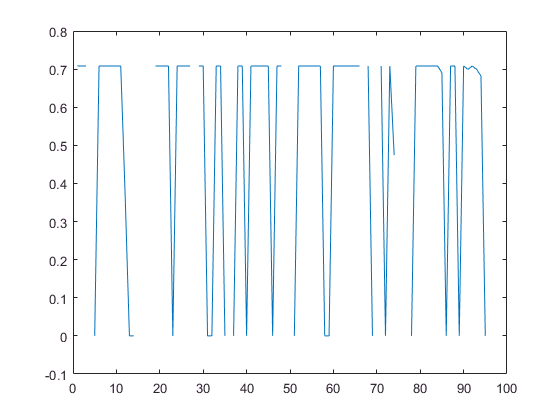

plot(grRateKO)

## **94.  **Reduced cost.

The reduced cost analysis can be used to identify those reactions that can reduce the growth rate (positive cost value). Reduced cost demonstrated as as part of step 89.

**95.  Print Matlab model content.  **

- Add a field if missing:

if ~isfield(modelEcore, 'osense')
    modelEcore.osense = -1;
end
if ~isfield(modelEcore, 'csense')
    modelEcore.csense(1:length(modelEcore.mets), 1) = 'E';
end

- Write a SBML file:

writeCbModel(modelEcore, 'sbml', 'EColiCore.xml')

Document written


ans =              constraint: [1×0 struct]
     functionDefinition: [1×0 struct]
                  event: [1×0 struct]
                   rule: [1×0 struct]
         unitDefinition: [1×1 struct]
      initialAssignment: [1×0 struct]
             SBML_level: 3
           SBML_version: 1
             annotation: ''
              areaUnits: ''
        avogadro_symbol: ''
       conversionFactor: ''
           delay_symbol: ''
            extentUnits: ''
    fbc_activeObjective: 'obj'
            fbc_version: 2
                     id: 'COBRAModel'
            lengthUnits: ''
                 metaid: 'COBRAModel'
                   name: ''
                  notes: ''
                sboTerm: -1
         substanceUnits: ''
              timeUnits: ''
            time_symbol: ''
               typecode: 'SBML_MODEL'
            volumeUnits: ''
                species: [1×72 struct]
            compartment: [1×2 struct]
              parameter: [1×7 struct]
               reaction: [1×95 st

## TIMING

The tutorial runs as given in a few seconds to minutes. However, if you use this tutorial for debugging and generating your own model, please consider the timing of the steps, as they have been given in the original protocol [1].

The timing of the entire reconstruction process depends on the properties of the target organism (prokaryote vs. eukaryote, genome size), the quality of the genome annotation, and the availability of experimental data. 

The timing listed below represents an average and can be used to plan the different stages. 

Step 1 - 4 (Stage 1, draft reconstruction): days to a week.

Step 5 (Stage 1, collection of experimental data): ongoing throughout the reconstruction process

Step 6 - 23 (Stage 2, reconstruction refinement): months to a year (if debugging and gap filling is done along the way)

Step 24 - 32 (Stage 2, biomass determination): days to weeks, depending on data availability 

Step 34 - 36 (Stage 2, biomass determination): days to a week. 

Step 37 (Stage 2, growth requirements): days to weeks, depending on data availability 

Step 38 - 42 (Stage 3, conversion): days to a week.

Step 43 - 94 (Stage 4, network evaluation/debugging): week to months.

Step 95 - 96 (Data assembly): days to weeks, depending how much and in which format data was collected.

## **TROUBLESHOOTING**

As given in original protocol [1].

Step 38    See installation instructions of the COBRA Toolbox for details on how to install and setup Matlab, SBML and COBRA Toolbox.

Step 51    Make sure that you are working in the directory were the X3.exe script was copied to. The .expa file produced by the function must be in the same directory as X3.exe. 

## **ANTICIPATED RESULTS**

As given in original protocol [1].

This protocol will result in a reconstruction that covers most of the known metabolic information of the target organism and represents a knowledge database. This reconstruction can be used as a resource for information (query tool), high-throughput data mapping (context for content), and a starting point for mathematical models. 

## References

[1] Thiele I, Palsson BO: A protocol for generating a high-quality genome-scale metabolic reconstruction. Nat Protoc 2010, 5:93-121.

[2] Orth JD, Fleming RM, Palsson BO: Reconstruction and Use of Microbial Metabolic Networks: the Core Escherichia coli Metabolic Model as an Educational Guide. EcoSal Plus 2010, 4.

[3] Feist AM, Henry CS, Reed JL, Krummenacker M, Joyce AR, Karp PD, Broadbelt LJ, Hatzimanikatis V, Palsson BO: A genome-scale metabolic reconstruction for Escherichia coli K-12 MG1655 that accounts for 1260 ORFs and thermodynamic information. Molecular systems biology 2007, 3:121.

[4] *Geobacter** sulfurreducans*